%% Simulations and Data Storage
run("assignment_3.m");

## Pure time delay

pure_timedelay = 0.01;
SIM = sim('assignment_3_simulink');

t       = SIM.LKC_SIM.Time(:,1);
e_1     = SIM.LKC_SIM.Data(:,1);

figure;
hold on;
colors = {'b', 'r', 'g'};
plot(t, e_1, colors{1}, 'DisplayName','With timedelay e_1');

pure_timedelay = 0;
SIM = sim('assignment_3_simulink');

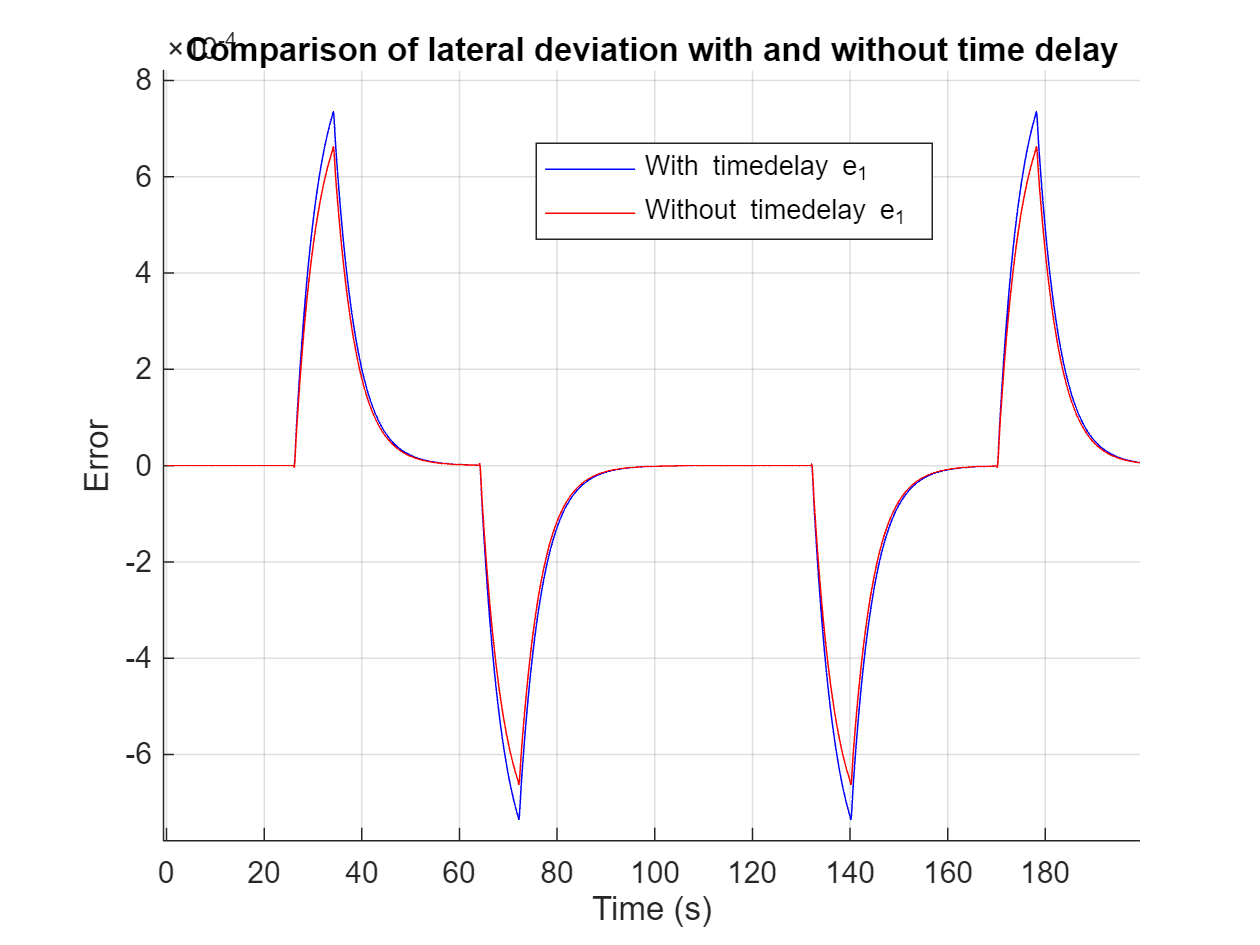


t       = SIM.LKC_SIM.Time(:,1);
e_1     = SIM.LKC_SIM.Data(:,1);

plot(t, e_1, colors{2}, 'DisplayName', 'Without timedelay e_1');

title('Comparison of lateral deviation with and without time delay');
xlabel('Time (s)');
ylabel('Error');
legend show;
grid on;

## Response for varying LQR tunings

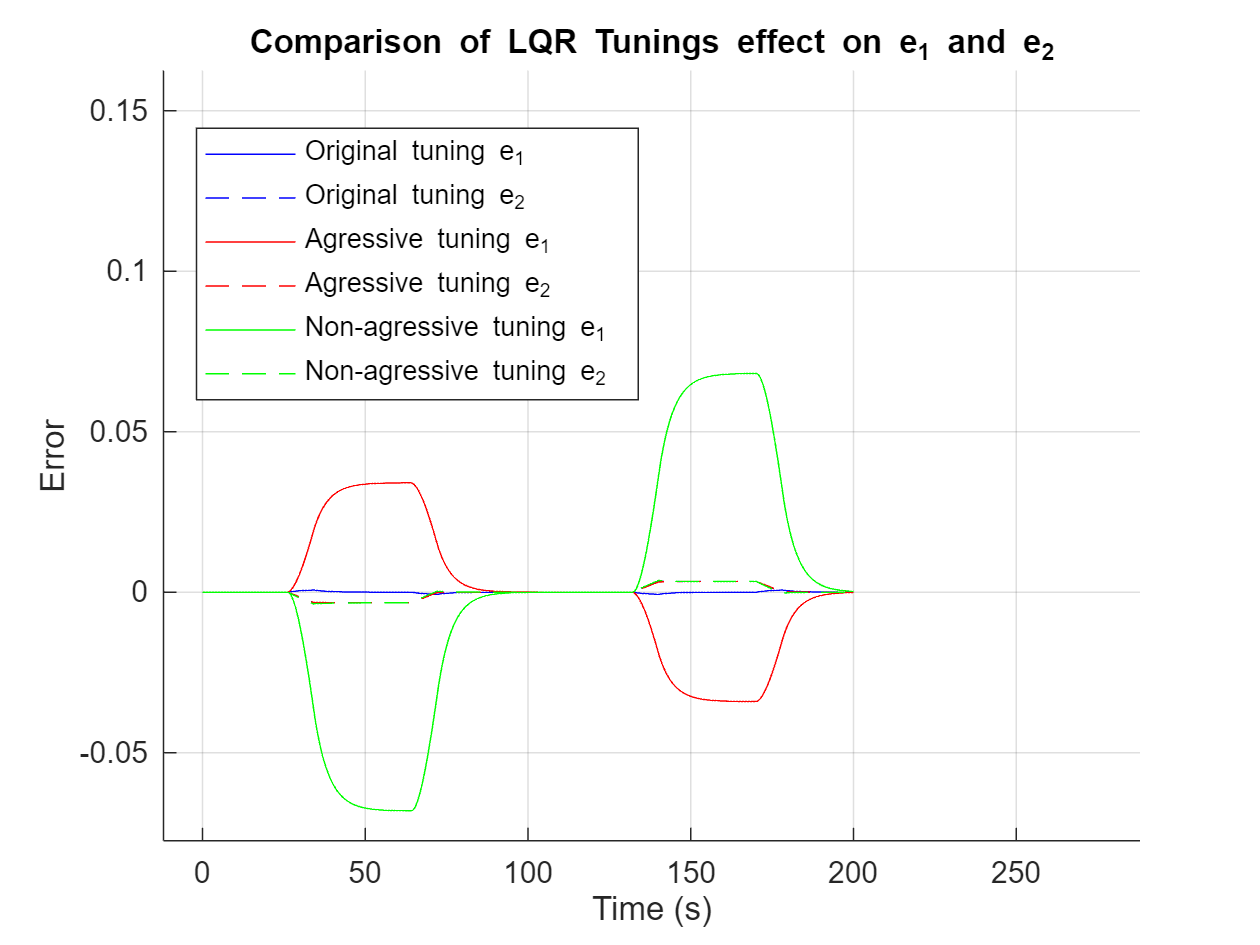


% Define the constant R matrix
R = 1;

% Different Q matrices for LQR tuning
Q1 = diag([10, 200, 10, 300]);  % Original tuning
Q2 = Q1*4;                      % More aggressive control on all states
Q3 = Q1/4;                      % Less aggressive control on all states

Q_matrices = {Q1, Q2, Q3};

% Store simulation results
simResults = struct();

for i = 1:length(Q_matrices)
    [K, ~, ~] = lqr(A, B_1, Q_matrices{i}, R);

    SIM = sim('assignment_3_simulink');

    t       = SIM.LKC_SIM.Time(:,1);
    e_1     = SIM.LKC_SIM.Data(:,1);
    e_1_dot = SIM.LKC_SIM.Data(:,2);
    e_2     = SIM.LKC_SIM.Data(:,3);
    e_2_dot = SIM.LKC_SIM.Data(:,4);

    simResults(i).time      = t;
    simResults(i).e_1       = e_1;
    simResults(i).e_1_dot   = e_1_dot;
    simResults(i).e_2       = e_2;
    simResults(i).e_2_dot   = e_2_dot;
end

% Plot the results
figure;
hold on;
colors = {'b', 'r', 'g'};
plot(simResults(1).time, simResults(1).e_1, colors{1}, 'DisplayName','Original tuning e_1');
plot(simResults(1).time, simResults(1).e_2, colors{1} + "--", 'DisplayName', 'Original tuning e_2');

plot(simResults(2).time, simResults(2).e_1, colors{2}, 'DisplayName', 'Agressive tuning e_1');
plot(simResults(2).time, simResults(2).e_2, colors{2} + "--", 'DisplayName', 'Agressive tuning e_2');

plot(simResults(3).time, simResults(3).e_1, colors{3}, 'DisplayName', 'Non-agressive tuning e_1');
plot(simResults(3).time, simResults(3).e_2, colors{3} + "--", 'DisplayName', 'Non-agressive tuning e_2');


title('Comparison of LQR Tunings effect on e_1 and e_2');
xlabel('Time (s)');
ylabel('Error');
legend show;
grid on;

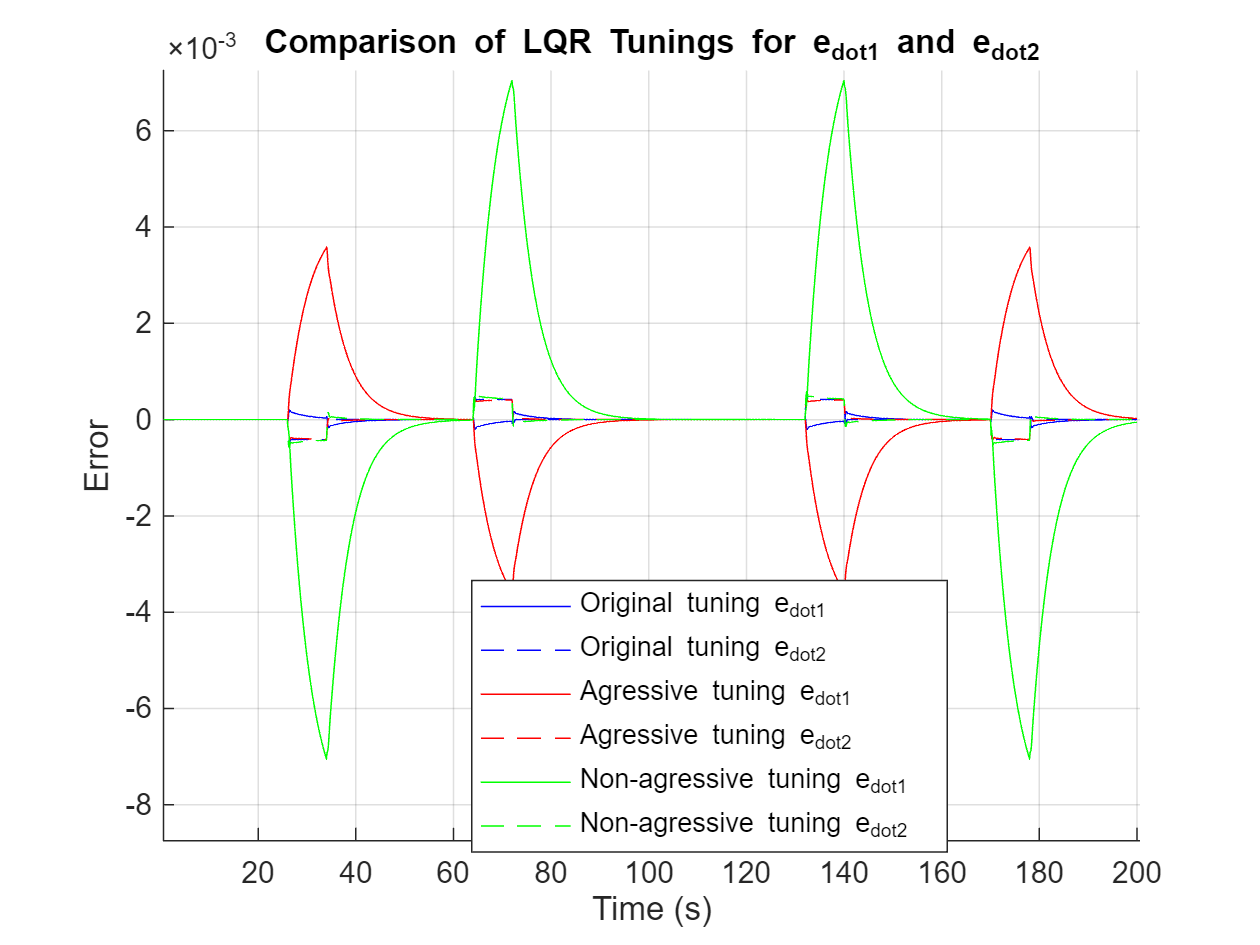


figure;
hold on;
colors = {'b', 'r', 'g'};
plot(simResults(1).time, simResults(1).e_1_dot, colors{1}, 'DisplayName','Original tuning e_{dot}_1');
plot(simResults(1).time, simResults(1).e_2_dot, colors{1} + "--", 'DisplayName', 'Original tuning e_{dot}_2');

plot(simResults(2).time, simResults(2).e_1_dot, colors{2}, 'DisplayName', 'Agressive tuning e_{dot}_1');
plot(simResults(2).time, simResults(2).e_2_dot, colors{2} + "--", 'DisplayName', 'Agressive tuning e_{dot}_2');

plot(simResults(3).time, simResults(3).e_1_dot, colors{3}, 'DisplayName', 'Non-agressive tuning e_{dot}_1');
plot(simResults(3).time, simResults(3).e_2_dot, colors{3} + "--", 'DisplayName', 'Non-agressive tuning e_{dot}_2');

title('Comparison of LQR Tunings for e_{dot}_1 and e_{dot}_2');
xlabel('Time (s)');
ylabel('Error');
legend show;
grid on;

## Lateral deviation for Varying Rear Axle Stiffness'

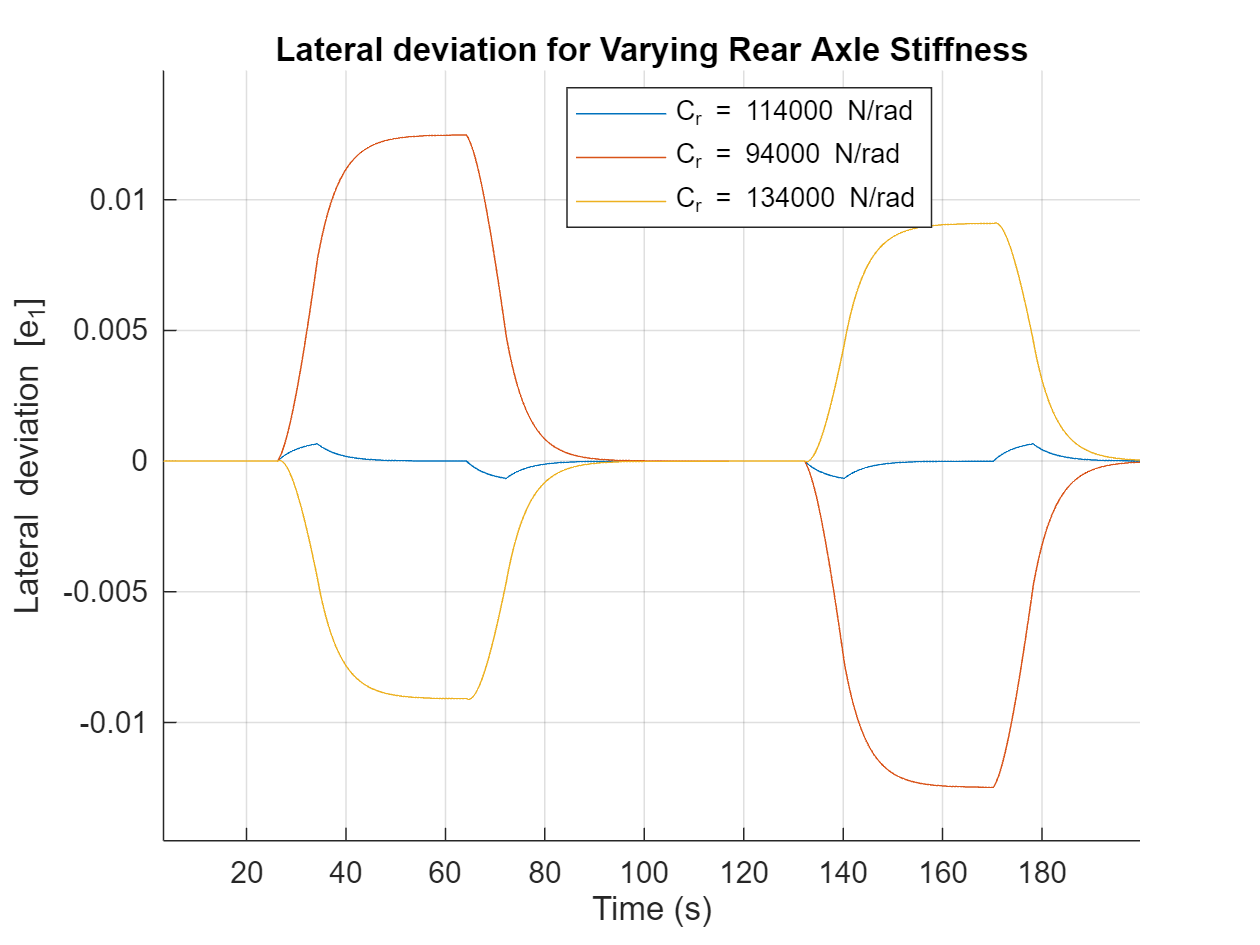

C_r_values = [2 * 57000, 2 * 47000, 2 * 67000]; % Original, decreased, and increased

figure;
hold on;

for i = 1:length(C_r_values)
    C_r = C_r_values(i);
    
    A = [0, 1, 0, 0;
         0, -(C_f + C_r) / (m_v * V_x), (C_f + C_r) / m_v, (C_r * l_r - C_f * l_f) / (m_v * V_x);
         0, 0, 0, 1;
         0, (C_r * l_r - C_f * l_f) / (J_psi * V_x), (C_f * l_f - C_r * l_r) / J_psi, -(C_r * l_r^2 + C_f * l_f^2) / (J_psi * V_x)];
    B_1 = [0; C_f / m_v; 0; (C_f * l_f) / J_psi];

    [K, ~, ~] = lqr(A, B_1, Q, R);

    SIM   = sim('assignment_3_simulink');
    t     = SIM.LKC_SIM.Time(:,1);
    e_1   = SIM.LKC_SIM.Data(:,1);
    delta = SIM.LKC_SIM.Data(:,5); 
    
    plot(t, e_1, 'DisplayName', sprintf('C_r = %d N/rad', C_r));

end

title('Lateral deviation for Varying Rear Axle Stiffness');
xlabel('Time (s)');
ylabel('Lateral deviation [e_1]');
legend show;
grid on;

## Plot LQR-gain as function of velocity

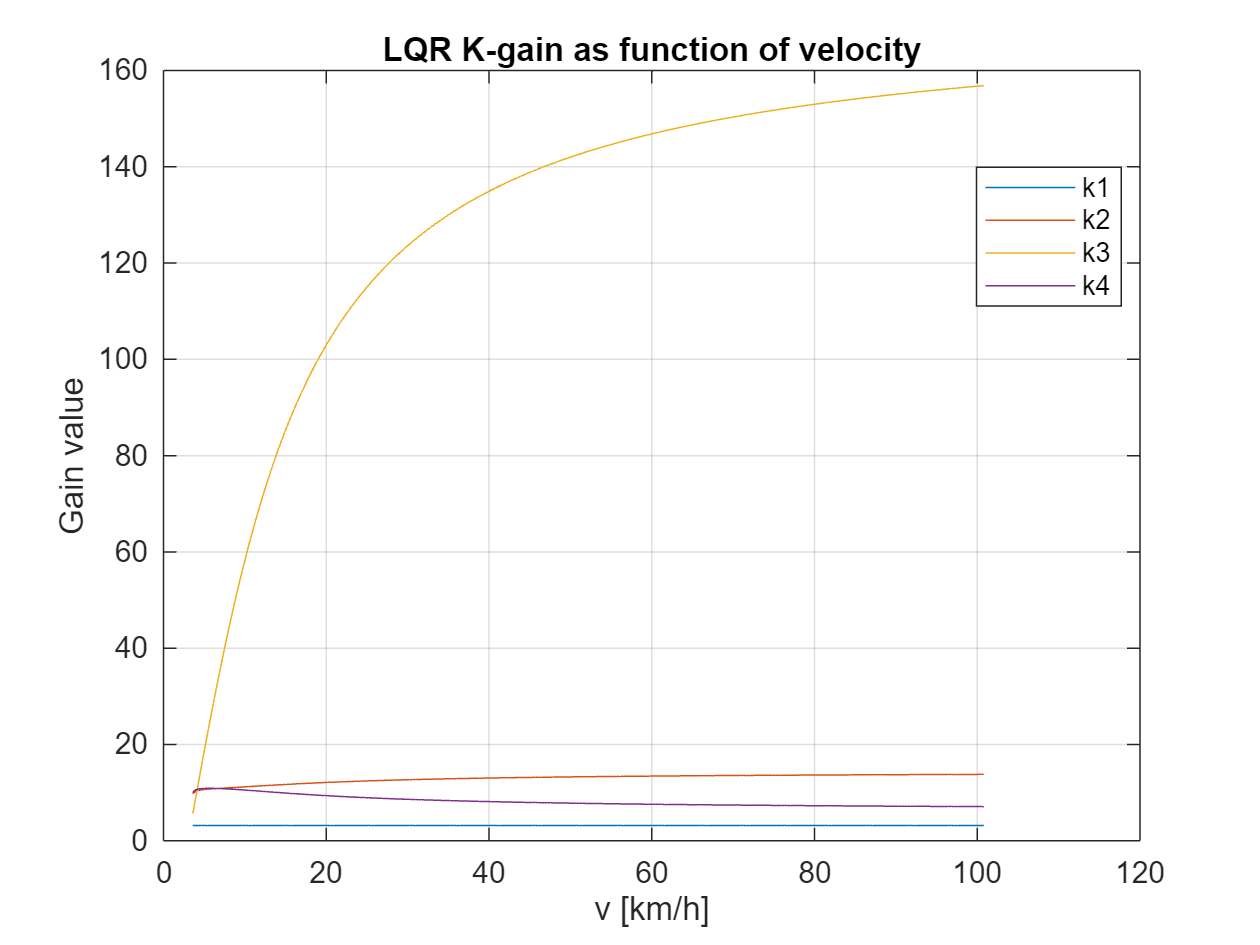

x = 1:0.1:28;

k1 = zeros(size(x));
k2 = zeros(size(x));
k3 = zeros(size(x));
k4 = zeros(size(x));

% Calculate values of k1, k2, k3, k4 for each x
for i = 1:length(x)
    ai_11 = 0;
    ai_12 = 1;
    ai_13 = 0;
    ai_14 = 0;
    
    ai_21 = 0;
    ai_22 = -(C_f + C_r)/(m_v*i);
    ai_23 = (C_f + C_r)/m_v;
    ai_24 = (C_r*l_r - C_f*l_f)/(m_v*i);
    
    ai_31 = 0;
    ai_32 = 0;
    ai_33 = 0;
    ai_34 = 1;
    
    ai_41 = 0;
    ai_42 = (C_r*l_r - C_f*l_f)/(J_psi*i);
    ai_43 = (C_f*l_f - C_r*l_r)/J_psi;
    ai_44 = -(C_r*l_r^2 + C_f*l_f^2)/(J_psi*i);
    
    b1i_1 = 0;
    b1i_2 = C_f/m_v;
    b1i_3 = 0;
    b1i_4 = (C_f*l_f)/J_psi;
    
    Ai = [ai_11 ai_12 ai_13 ai_14;
         ai_21 ai_22 ai_23 ai_24;
         ai_31 ai_32 ai_33 ai_34;
         ai_41 ai_42 ai_43 ai_44];
    
    Bi_1 = [b1i_1; b1i_2; b1i_3; b1i_4];
    
    C = eye(4);
    % Modify the A, B, Q, R matrices as needed for each x if they depend on x
    [K,S,P] = lqr(Ai,Bi_1,Q,R);
    k1(i) = K(1);
    k2(i) = K(2);
    k3(i) = K(3);
    k4(i) = K(4);
   
end
x = x*3.6;

% Plotting the values
figure;
plot(x, k1, 'DisplayName', 'k1');
hold on;
plot(x, k2, 'DisplayName', 'k2');
hold on
plot(x, k3, 'DisplayName', 'k3');
hold on;
plot(x, k4, 'DisplayName', 'k4');
hold off;

% Add labels and legend
xlabel('v [km/h]');
ylabel('Gain value');
title('LQR K-gain as function of velocity');
legend show;
grid on;